write MATLAB code to isolate text from an image

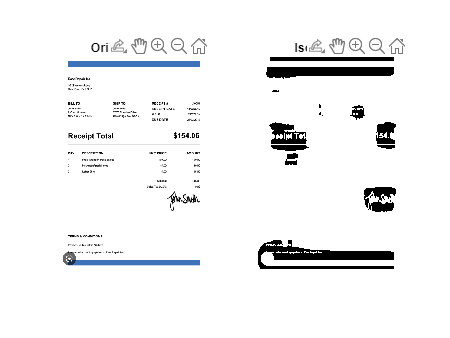

% Read the image
img = imread('Capture.PNG');

% Convert the image to grayscale
img_gray = rgb2gray(img);
% Apply adaptive thresholding to the grayscale image
img_bw = imbinarize(img_gray, 'adaptive');

% Remove small objects (noise) from the binary image
img_bw = bwareaopen(img_bw, 50);

% Invert the binary image to get the text
img_text = imcomplement(img_bw);

% Display the original and isolated text images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_text);
title('Isolated Text');

Write MATLAB code to add a moton blur effect to an image

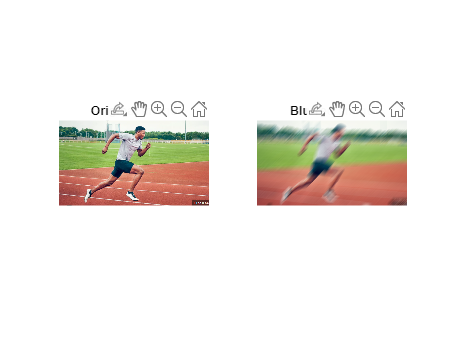

% Read the image
img = imread('running.PNG');

% Create a motion blur kernel
h = fspecial('motion', 30, 45);

% Apply the motion blur effect to the image
img_blurred = imfilter(img, h, 'replicate');

% Display the original and blurred images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_blurred);
title('Blurred Image');

Write MATLAB code to detect if there are cars in an image

% Read the image
img = imread('Group-Action-Willow-MotorTrends-PVOTY-2022.jpg');

% Load the pre-trained object detector

%vision.CascadeObject detector is trained on faces
%there is no pretrainde model for cars.
detector = vision.CascadeObjectDetector()

Error using vision.CascadeObjectDetector
Unable to find cars.xml.


% Detect cars in the image
bboxes = step(detector, img);

% Display the results
imshow(img);
hold on;
for i = 1:size(bboxes,1)
    rectangle('Position',bboxes(i,:),'LineWidth',2,'EdgeColor','r');
end
title('Detected Cars');
hold off;

Write matlab code to produce the negative of an image

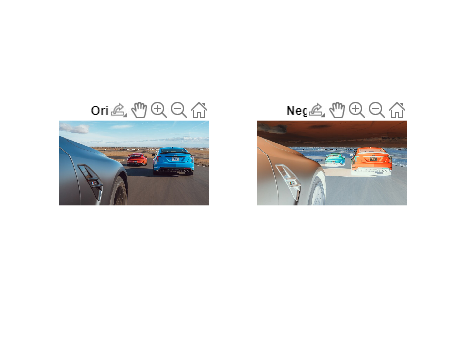

% Read the image
img = imread("Group-Action-Willow-MotorTrends-PVOTY-2022.jpg");

% Convert the image to double type
img = im2double(img);

% Calculate the negative of the image
img_negative = 1 - img;

% Display the original and negative images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_negative);
title('Negative Image');

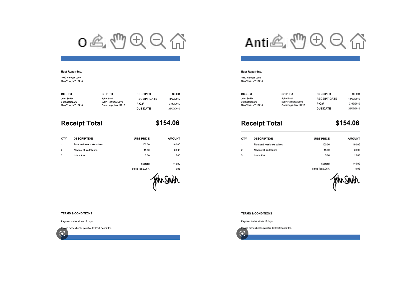

% Read the image
img = imread('Capture.PNG');

% Resize the image with anti-aliasing
img_anti_aliased = imresize(img, 2, 'Antialiasing', true);

% Display the original and anti-aliased images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_anti_aliased);
title('Anti-Aliased Image');